clear; clc; close all;

% =========================================================================
% ⚙️ ส่วนที่ 1: กำหนดข้อมูลสำหรับกราฟทั้งสองชุด
% =========================================================================

% --- ข้อมูลชุดที่ 1: คำนวณจากไฟล์ ---
x_axis_values = [0,139.5,178.3,219.6,310.3];
output_folder = "segments_output_3";

% --- ข้อมูลชุดที่ 2: กำหนดจุดด้วยตนเอง ---
%x_points_manual = [ 9.916, 19.99, 29.75, 40.03, 49.98, 60.03, 70.03, 80.00, 90.44];
%y_points_manual = [ 1.145, 2.624, 6.180, 10.94, 15.67, 22.81, 39.74, 63.72, 89.02];
% 1 y_points_manual = [ 0.787, 2.446, 6.097, 10.84, 15.66, 22.76, 40.00, 63.71, 89.21];
% 2 y_points_manual = [ 1.145, 2.624, 6.180, 10.94, 15.67, 22.81, 39.74, 63.72, 89.02];

% =========================================================================
% 🔄 ส่วนที่ 2: คำนวณค่าเฉลี่ยจากไฟล์ (สำหรับข้อมูลชุดที่ 1)
% =========================================================================
segment_files = dir(fullfile(output_folder, 'segment_*.mat'));
if isempty(segment_files)
    error('ไม่พบไฟล์ segment ในโฟลเดอร์ "%s"', output_folder);
end

all_averages = [];
fprintf('กำลังคำนวณค่าเฉลี่ยจากไฟล์...\n');

กำลังคำนวณค่าเฉลี่ยจากไฟล์...


for i = 1:length(segment_files)
    file_path = fullfile(output_folder, segment_files(i).name);
    data_in_file = load(file_path, 'y_segment');
    current_average = mean(data_in_file.y_segment);
    all_averages(i) = current_average;
    fprintf('✅ ประมวลผล %s -> ค่าเฉลี่ยดิบ: %.2f -> ค่าที่แปลงแล้ว: %.2f\n', ...
            segment_files(i).name, current_average, all_averages(i));
end

✅ ประมวลผล segment_01.mat -> ค่าเฉลี่ยดิบ: 1466.40 -> ค่าที่แปลงแล้ว: 1466.40
✅ ประมวลผล segment_02.mat -> ค่าเฉลี่ยดิบ: 2072.06 -> ค่าที่แปลงแล้ว: 2072.06
✅ ประมวลผล segment_03.mat -> ค่าเฉลี่ยดิบ: 2245.67 -> ค่าที่แปลงแล้ว: 2245.67
✅ ประมวลผล segment_04.mat -> ค่าเฉลี่ยดิบ: 2432.50 -> ค่าที่แปลงแล้ว: 2432.50
✅ ประมวลผล segment_05.mat -> ค่าเฉลี่ยดิบ: 2839.32 -> ค่าที่แปลงแล้ว: 2839.32


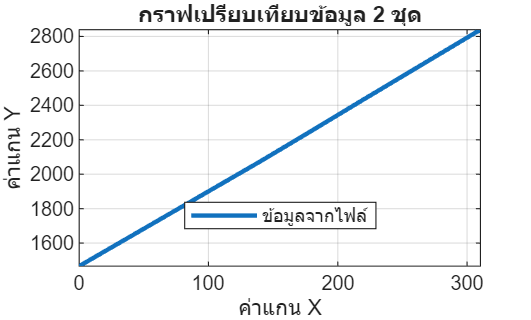


% =========================================================================
% ⚠️ ส่วนที่ 3: ตรวจสอบความถูกต้องของข้อมูล
% =========================================================================
if length(x_axis_values) ~= length(all_averages)
    error(['จำนวนค่าใน x_axis_values (%d) ไม่ตรงกับจำนวนไฟล์ segment ที่พบ (%d)!'], ...
           length(x_axis_values), length(all_averages));
end
%if length(x_points_manual) ~= length(y_points_manual)
%    error('จำนวนข้อมูลในแกน X และ Y ของชุดข้อมูลที่กำหนดเองไม่เท่ากัน!');
%end

% =========================================================================
% 📊 ส่วนที่ 4: สร้างกราฟพร้อม Error Bar (ไม่มีจุดอ้างอิง)
% =========================================================================
figure; 

% --- พล็อตกราฟเส้นที่ 1 (จากไฟล์) ---
plot(x_axis_values, all_averages, '-', 'LineWidth', 2, 'DisplayName', 'ข้อมูลจากไฟล์');

hold on;

% --- ✨ ส่วนที่เปลี่ยนแปลง ✨ ---
% 1. คำนวณค่าความคลาดเคลื่อน 20% สำหรับข้อมูลชุดที่ 2
%error_margin = 0.20; % 20%
%error_values = y_points_manual * error_margin; % คำนวณค่า error ของแต่ละจุด

% 2. พล็อตกราฟเส้นที่ 2 โดยไม่ใช้ marker
%    'DisplayName', 'ข้อมูลที่กำหนดเอง (คลาดเคลื่อน 20%)', 'CapSize', 8);

hold off;

% --- ตกแต่งกราฟ ---
title('กราฟเปรียบเทียบข้อมูล 2 ชุด');
xlabel('ค่าแกน X');
ylabel('ค่าแกน Y');
grid on;
axis tight;
legend('show', 'Location', 'best');


disp('🎉 สร้างกราฟรวมเรียบร้อย (ไม่มีจุดอ้างอิง)!');

🎉 สร้างกราฟรวมเรียบร้อย (ไม่มีจุดอ้างอิง)!
